Level 1

sample_values1 = double_stunted_gaussian_inverse_gamma(rand(1,1e3),1/2,1/20);
tolerance = 1; % in basis points

[profit1,palpha1,pbeta1] = classical_profit_from_sample(sample_values1,tolerance)

profit1 = 0.0291

palpha1 = 0.5310

pbeta1 = 0.4711

Level 2

% Eliminate Previously Used Bet-Probability Pairs

sample_values2 = sample_values1(sample_values1>pbeta1 & sample_values1<palpha1);

[profit2,palpha2,pbeta2] = classical_profit_from_sample(sample_values2,tolerance)

profit2 = 0.0131

palpha2 = 0.5143

pbeta2 = 0.4897

Level 3

% Eliminate Previously Used Bet-Probability Pairs

sample_values3 = sample_values2(sample_values2>pbeta2 & sample_values2<palpha2);

[profit3,palpha3,pbeta3] = classical_profit_from_sample(sample_values3,tolerance)

profit3 = 2.4578e-04

palpha3 = 0.5140

pbeta3 = 0.4897

Looking At The Values Used

h1 = histogram(sample_values1);
hold on
h2 = histogram(sample_values2);
h3 = histogram(sample_values3);
remaining_values = sample_values3(sample_values3>pbeta3 & sample_values3<palpha3); 
hr = histogram(remaining_values);

% Equalize BinWidths to Standardize Height
h1.BinWidth = hr.BinWidth;
h2.BinWidth = hr.BinWidth;
h3.BinWidth = hr.BinWidth;
legend({'Iteration 1','Iteration 2','Iteration 3','Remainder'})
title('Iterative MoneyLines')
ylabel('Qunatity (out of 1000)')
xlabel('Probability')


Trends

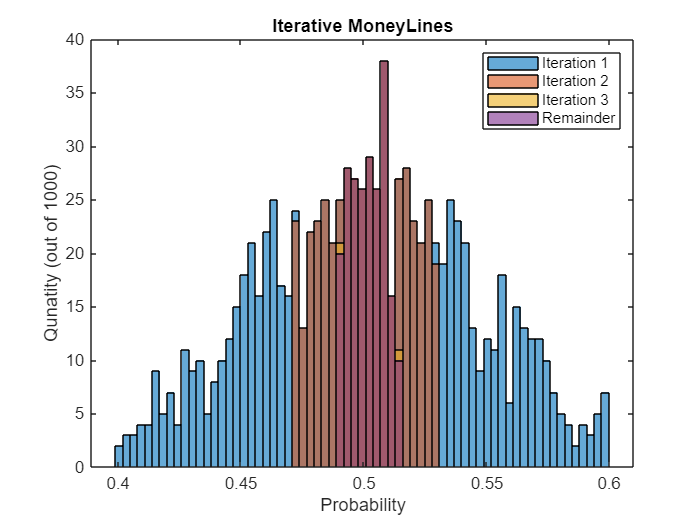

hold off

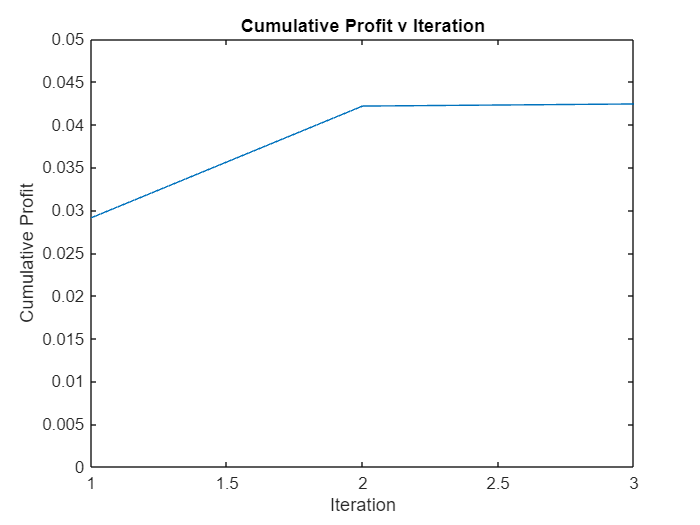

plot(1:3,cumsum([profit1 profit2 profit3]))
xlabel('Iteration')
ylabel('Cumulative Profit')
title('Cumulative Profit v Iteration')
ylim([0 .05])

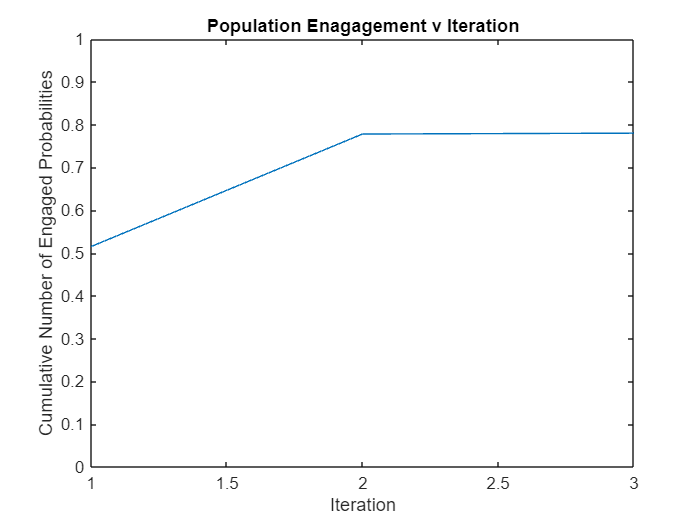


plot(1:3,(1000-[length(sample_values2) length(sample_values3) length(remaining_values)])/1000)
xlabel('Iteration')
ylabel('Cumulative Number of Engaged Probabilities')
title('Population Enagagement v Iteration')
ylim([0 1])

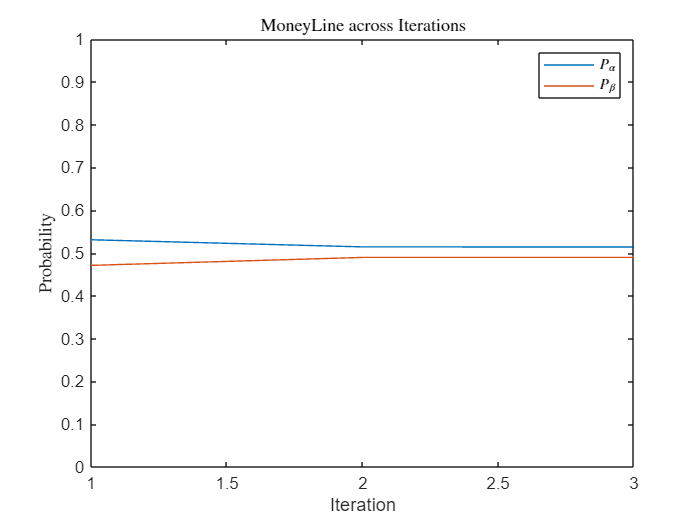


plot(1:3,[palpha1 palpha2 palpha3])
hold on
plot(1:3,[pbeta1 pbeta2 pbeta3])
xlabel('Iteration')
ylabel('Probability','Interpreter','latex')
legend({'$P_{\alpha}$','$P_{\beta}$'},'Interpreter','latex')
title('MoneyLine across Iterations','Interpreter','latex')
ylim([0 1])
hold off

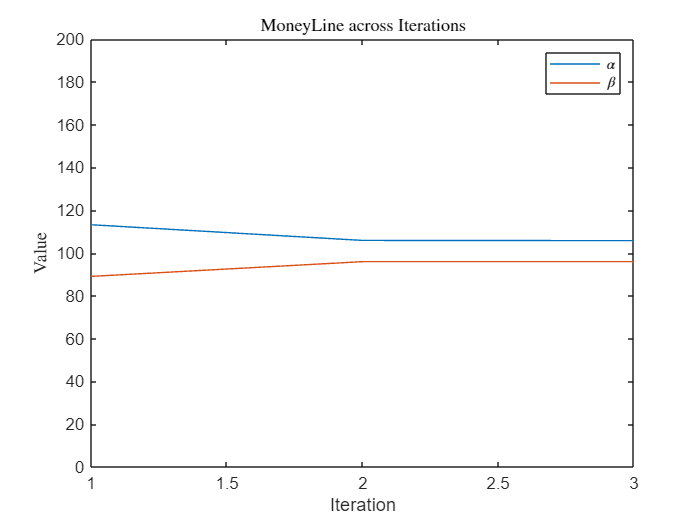



plot(1:3,100*[palpha1 palpha2 palpha3]./(1-[palpha1 palpha2 palpha3]))
hold on
plot(1:3,100*[pbeta1 pbeta2 pbeta3]./(1-[pbeta1 pbeta2 pbeta3]))
xlabel('Iteration')
ylabel('Value','Interpreter','latex')
legend({'$\alpha$','$\beta$'},'Interpreter','latex')
title('MoneyLine across Iterations','Interpreter','latex')
ylim([0 200])
hold off

Profit Comparison with Peer to Peertr

traditional_inception_profit = sum([profit1 profit2 profit3])

traditional_inception_profit = 0.0424

peer2peer_profit = peer2peer_profit_from_sample(sample_values1,100)

peer2peer_profit = 0.0620